# **Kalman filter**

## Introduction to Kalman filter for Asset replication

Here we intend to exploit Kalman filter for Asset replication. 

Some technical papers and books we can refer to:

1. “An Introduction to the Kalman Filter” by Gary Welch & Gary Bishop, 2006 

2. “An Alternative Approach to Alternative Beta” by Thierry Roncalli & Jerome Teiletche, 2008 

3. “Asset Replication” by Rupak Chatterjee, 2014

4. “Tracking Problems, Hedge Fund Replication and Alternative Beta.” by Thierry Roncalli & Guillaume Weisang, 2011 

5. “Introduction to Random Signals and Applied Kalman Filtering.” by Robert Grover Brown & Patrick Y. C. Hwang, 2012

In the pursuit of delivering returns comparable to a specific index, a replication strategy emerges as a promising approach. By incorporating improved liquidity, transparency, and simplicity, this strategy seeks to enhance investment outcomes. Nevertheless, research has uncovered a tradeoff associated with utilizing more liquid and transparent replication methods, as they tend to underperform relative to the target index.

In this presentation, our focus is to explore the implementation of the Kalman Filter estimation algorithm in constructing a portfolio consisting of highly liquid contracts. The objective is to replicate or even outperform the returns of a designated index, referred to as the 'monster index.' This approach enables us to capitalize on the advantages of heightened transparency, simplicity, and improved liquidity while striving for superior investment outcomes.

### Kalman Filter Basics

The Kalman Filter is a powerful mathematical tool utilized in the estimation of hidden states, leveraging a sequence of noisy observations.

 • As a recursive algorithm, it produces optimal estimates of the state by assuming linearity in the state transition process and mappings to observable measurements.

 • With its ability to support estimations of past, present, and even future states, the Kalman Filter proves valuable in modeling systems even when their precise nature remains unknown.

## Asset Replication Bacics

In the realm of investments, asset replication revolves around mirroring the returns of a specific asset using the returns generated by another asset or a combination of multiple assets. This approach comes into play when the asset being replicated lacks direct tradability or desired liquidity. To gain exposure to the replicated asset or index, investors turn to alternative instruments such as cash instruments, derivatives, or exchange-traded funds (ETFs). These financial tools enable investors to achieve similar returns while navigating the constraints posed by the original asset's limited market accessibility or liquidity.

### Filter implementation

Follows the relative linear system:

We impose the weights of the features to be constant in time, plus a certain noise due to the variance of the features:

x(t+1) = x(t) + v1(t)

where x(t) is the state variable indicating the futures weights. 

We ask for equality of the returns, considering an additional noise:

y(t) = Ax(t) + v2(t) 

where A is the matrix of futures returns.

% Synthetic target weights
wHFRXGL = 0.5; 
wMXWO = 0.25;
wLEGATRUU = 0.25;

% Define the state variables
x = [wHFRXGL wMXWO wLEGATRUU];

% Building the target, observation variables 
y = wHFRXGL*price2ret(HFRXGL) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
% target = (ret2price(y)); % "Monster Index" levels

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];
% L'LLL1 ha un comportamento BELLO STRANO 

## EGARCH MODEL FOR VARIANCE ESTIMATION

The Generalized Autoregressive Conditional Heteroskedasticity (GARCH) model is a statistical model used for estimating and forecasting the variance of a time series. It is an extension of the autoregressive moving average (ARMA) model, which captures the linear dependencies in a time series. However, the GARCH model also takes into account the conditional heteroskedasticity, meaning that the variance of the series is not constant over time but depends on past observations. The GARCH model is estimated by fitting the model parameters to the observed data using methods such as maximum likelihood estimation. Once the model is estimated, it can be used to estimate and forecast the conditional variance of the time series. These estimates can be valuable for risk management, portfolio optimization, option pricing, and other applications in finance. 

The Exponential Generalized Autoregressive Conditional Heteroskedasticity (EGARCH) model is an extension of the GARCH model that addresses asymmetry and leverage effects in the conditional variance of a time series.

Let's start by converting data into timetable format. We consider each future separately. 

T1 = timetable(Date,ret2price(X(:,1)));
T2 = timetable(Date,ret2price(X(:,2)));
T3 = timetable(Date,ret2price(X(:,3)));
T4 = timetable(Date,ret2price(X(:,4)));
T5 = timetable(Date,ret2price(X(:,5)));
%LLL1 has not a gaussian distribution 
T6 = timetable(Date,ret2price(X(:,6)));
T7 = timetable(Date,ret2price(X(:,7)));
T8 = timetable(Date,ret2price(X(:,8)));
T9 = timetable(Date,ret2price(X(:,9)));
T10 = timetable(Date,ret2price(X(:,10)));
T11 = timetable(Date,ret2price(X(:,11)));

mdl1 = EGARCH_Logreturns1;
V1 = infer(mdl1,Logreturns1); % Infer conditional variance
mdl2 = EGARCH_Logreturns2;
V2 = infer(mdl2,Logreturns2); % Infer conditional variance
mdl3 = EGARCH_Logreturns3;
V3 = infer(mdl3,Logreturns3); % Infer conditional variance
mdl4 = EGARCH_Logreturns4;
V4 = infer(mdl4,Logreturns4); % Infer conditional variance

V5 = eye(704,1).*var(X(:,5)); % Infer variance

mdl6 = EGARCH_Logreturns6;
V6 = infer(mdl6,Logreturns6); % Infer conditional variance
mdl7 = EGARCH_Logreturns7;
V7 = infer(mdl7,Logreturns7); % Infer conditional variance
mdl8 = EGARCH_Logreturns8;
V8 = infer(mdl8,Logreturns8); % Infer conditional variance
mdl9 = EGARCH_Logreturn9;
V9 = infer(mdl9,Logreturn9); % Infer conditional variance
mdl10 = EGARCH_Logreturns10;
V10 = infer(mdl10,Logreturns10); % Infer conditional variance
mdl11 = EGARCH_Logreturns11;
V11 = infer(mdl11,Logreturns11); % Infer conditional variance

Perform time series modeling using Econometrics Modeler App:

 econometricModeler

The chart is automatically reported. We invert prices into returns just performing logarithmic and differences transformations. We see that the logreturns exhibit conditional error heteroscedasticity ( autocorrelation in the square series ). We perform Engle's ARCH test to prove heteroscedasticity. The null hypothesis is that Logreturns exhibits no ARCH effects. It's rejected. Then we perform a GARCH ( one-one ), the EGARCH and GJR. Looking at the goodness of fit, we observe the model with lowest AIC and BIC is the EGARCH. Finally, we perform residual diagnostics with Q-Q plot. The residuals are approximately normal. 

 variances = [V1 V2 V3 V4 V5 V6 V7 V8 V9 V10 V11]; % varianze condizionali 

rollingWindow = 26; % in weeks (52 = 1Y, 104 = 2Y...)
i = 1;
b = zeros(size(X,2));
bENet2 = [];
rENet2 = [];
GrossExposure = [];
endSample = 0;
warning('off','all'); % avoid annoying warnings during the loop

while endSample <= (length(X) - 2)
    startSample = i;
    endSample = i+rollingWindow-1;
   
    % Set up the state-space model 
    m = 11;
    F = eye(m);
    H = X(startSample:endSample,:); % time-depending 
   % V2 = ones(156,1).*std(y(startSample:endSample));
    V2 = zeros(156,1);
    %V1 = eye(m).*var(X(startSample:endSample,:))';

    %Initialization 
    x_0 = zeros(1,m);
    P = ones(m,m);
    F = eye(m,m);
    y_meas = y(startSample:endSample); %time-depending
    x_corr = zeros(length(y_meas), m);
    x_pred = zeros(length(y_meas), m);
    x_pred(1,:) = x_0;
    K = zeros(m,length(y_meas));
 

    for t = 1:length(y_meas)
      V1 = eye(m).*variances(t);
      % Correction step
      [K_t, x_corr_t] = kf_correction(y_meas, H, V2, x_pred,P,t,F);
      K(:,t) = K_t;
      x_corr(t,:) = x_corr_t;
      % Prediction step
      [x_pred_t, P_pred] = kf_prediction(F, V1, x_corr_t, P, H,t);
      P = P_pred;
      x_pred(t,:) = x_pred_t;
    end

    b = x_pred_t;
    GrossExposure = [GrossExposure; sum(abs(b))];
    bENet2 = [bENet2; b];
    r = X(endSample + 1,:)*b';
    rENet2 = [rENet2; r];
    i = i+1;
end

warning('on','all'); % warnings on again

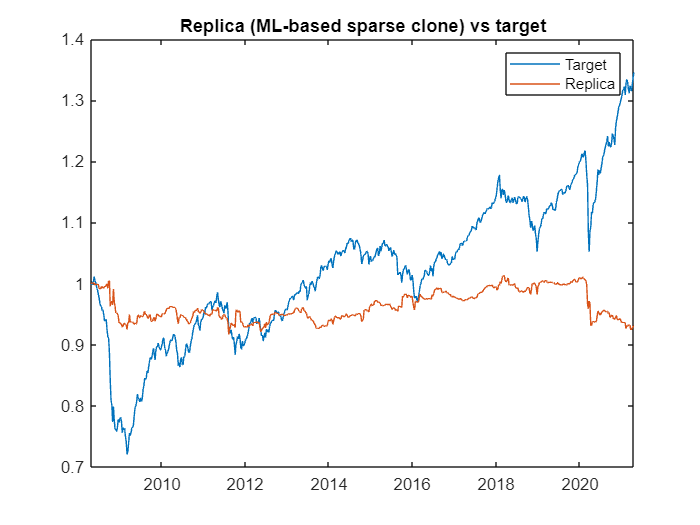

figure
plot(Date(rollingWindow+1:end),ret2price(y(rollingWindow + 1: end)),'DisplayName','Target');
hold on;
plot(Date(rollingWindow+1:end),ret2price(rENet2),'DisplayName','Replica');
legend
title('Replica (ML-based sparse clone) vs target')
hold off;

Let's envision the returns generated by the acquired weights. 

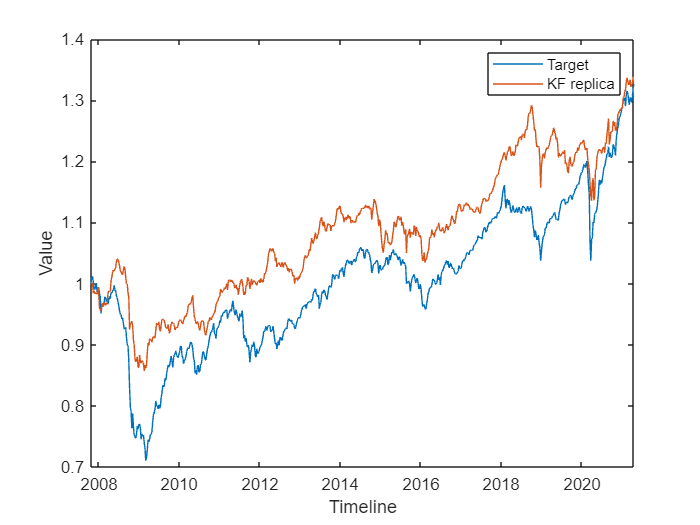

replRetKF = X*b'; % compute portfolio returns using regression coefficients as weights
repKF = ret2price(replRetKF); % from returns to levels

figure
plot(XTab.Date,ret2price(y),'DisplayName','Target');
hold on;
plot(XTab.Date,repKF,'DisplayName','KF replica');
xlabel('Timeline')
ylabel('Value')
legend
hold off;

#### Piuttosto che mettere questa gran cagata mostra come migliora tra usare le varianze stimate e le varianze condizionate. 

Idea: we want to cluster weeks in periods with high, medium or small volatility. The intuition is that our replicating portfolio behaves badly in periods with high volatility. So when it happens we want it to replicate another return that is corrected by the avarage loss. 

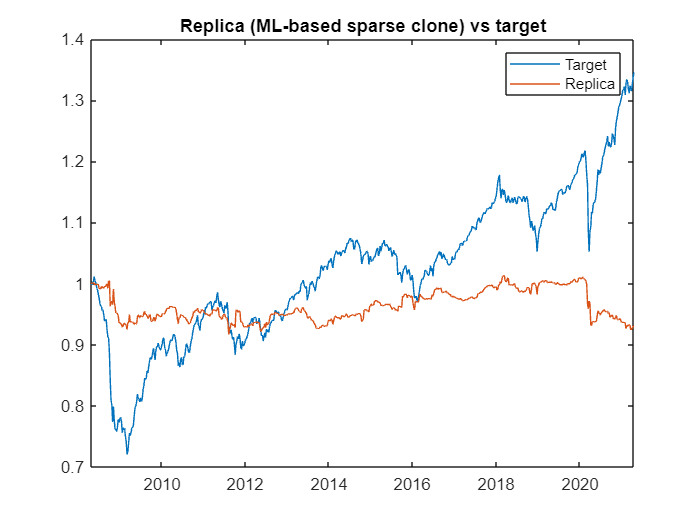

%Monthly volatility
num_months = floor(length(y) / 4);
std_vector = zeros(num_months,1);
for i = 1:num_months
    if i == 1
        std_vector(i) = std(y(1:4));
    else 
    std_vector(i) = std(y((i-1)*4:i*4));
    end
end
%Clustering of volatilities
idx = kmeans(std_vector,2);
months = [1:num_months;std_vector';idx'];

%months with high volatility
high_months = months(1, months(3, :) == 2);
diff = y - replRetKF;

tracking_error = mean(diff);
y_new = y;

%correction of high volatility periods
for i = high_months
    if i == 1 
        y_new(1:4) = y(1:4) - tracking_error;  
    else 
        y_new((i-1)*4:i*4) = y((i-1)*4:i*4) - tracking_error;
    end
end

% Use again the KF, this time with ynew


rollingWindow = 26; % in weeks (52 = 1Y, 104 = 2Y...)
i = 1;
b1 = zeros(size(X,2));
bENet22 = [];
rENet22 = [];
GrossExposure = [];
endSample = 0;
warning('off','all'); % avoid annoying warnings during the loop

while endSample <= (length(X) - 2)
    startSample = i;
    endSample = i+rollingWindow-1;
   
    % Set up the state-space model 
    m = 11;
    F = eye(m);
    H = X(startSample:endSample,:); % time-depending 
   % V2 = ones(156,1).*std(y(startSample:endSample));
    V2 = zeros(156,1);
    %V1 = eye(m).*var(X(startSample:endSample,:))';


    %Initialization 
    x_0 = zeros(1,m);
    P = ones(m,m);
    F = eye(m,m);
    y_meas = y_new(startSample:endSample); %time-depending
    x_corr = zeros(length(y_meas), m);
    x_pred = zeros(length(y_meas), m);
    x_pred(1,:) = x_0;
    K = zeros(m,length(y_meas));
 

    for t = 1:length(y_meas)
      V1 = eye(m).*variances(t);
      % Correction step
      [K_t, x_corr_t] = kf_correction(y_meas, H, V2, x_pred,P,t,F);
      K(:,t) = K_t;
      x_corr(t,:) = x_corr_t;
      % Prediction step
      [x_pred_t, P_pred] = kf_prediction(F, V1, x_corr_t, P, H,t);
      P = P_pred;
      x_pred(t,:) = x_pred_t;
    end

    b1 = x_pred_t;
    GrossExposure = [GrossExposure; sum(abs(b1))];
    bENet22 = [bENet22; b1];
    r = X(endSample + 1,:)*b1';
    rENet22 = [rENet22; r];
    i = i+1;
end

warning('on','all'); % warnings on again

figure
plot(Date(rollingWindow+1:end),ret2price(y(rollingWindow + 1: end)),'DisplayName','Target');
hold on;
plot(Date(rollingWindow+1:end),ret2price(rENet22),'DisplayName','Replica');
legend
title('Replica (ML-based sparse clone) vs target')
hold off;

replRetKF1 = X*b1'; % compute portfolio returns using regression coefficients as weights
repKF1 = ret2price(replRetKF1); % from returns to levels

figure
plot(XTab.Date,ret2price(y),'DisplayName','Target');
hold on;
plot(XTab.Date,repKF1,'DisplayName','KF replica');
xlabel('Timeline')
ylabel('Value')
legend
hold off;

### KF Portofolio Replication Results

In order to assess the performance of the KF replication portfolio in aligning with its benchmark index, several tracking statistics are computed for each portfolio across different time horizons. These statistics include the RMS tracking error, average tracking error, standard deviation of tracking error, monthly correlation, and quarterly correlation. These metrics provide valuable insights into the extent to which the KFMI replication portfolio closely follows the movements of the index.

% RMSE
RMS = rmse(replRetKF,y)

RMS = 0.0089


RMS2 = rmse(replRetKF1,y)

RMS2 = 0.0089

This indicates a relatively accurate replication or tracking of the target index's returns by the portfolio. When it comes to asset replication using futures contracts, a commonly used benchmark is to compare the RMSE with the tracking error of an index-tracking mutual fund or an ETF that aims to replicate the same target index. The tracking error measures the deviation between the fund's returns and the target index's returns.

Typically, a lower tracking error is desirable, indicating a better replication of the index. For actively managed funds, tracking errors below 1% are often considered good, while for passive index-tracking funds, the tracking error is expected to be even lower, often below 0.5%.

% Avarage tracking error
[InfoRatio, TrackingError] = inforatio(replRetKF, y)

InfoRatio = 0.0016

TrackingError = 0.0089

[InfoRatio1, TrackingError1] = inforatio(replRetKF1, y)

InfoRatio1 = 0.0016

TrackingError1 = 0.0089

- InfoRatio: The InfoRatio is a measure of the excess return generated by the replicating portfolio relative to a benchmark index, adjusted for the risk taken. A negative InfoRatio of -0.0225 suggests that the replicating portfolio, on average, underperformed the benchmark index by that amount after accounting for risk.

- TrackingError: The TrackingError quantifies the volatility or dispersion of returns between the replicating portfolio and the target index. A TrackingError of 0.005 indicates that, on average, the difference between the replicating portfolio's returns and the target index's returns was relatively small. This suggests a relatively accurate replication or tracking of the target index's returns by the portfolio.

Overall, while the TrackingError indicates a good level of accuracy in replicating the target index's returns, the negative InfoRatio suggests that the replicating portfolio failed to outperform the benchmark index on average, considering the risk taken. This indicates a potential room for improvement in the portfolio's performance relative to the benchmark.

Remark on difference between RMSE e Tracking error:

TrackingError: TrackingError quantifies the volatility or dispersion of returns between the replicating portfolio and the target index. It measures the standard deviation of the differences between the returns of the replicating portfolio and the returns of the target index. A lower TrackingError indicates a smaller deviation between the two sets of returns, suggesting a better replication or tracking of the target index.

RMSE (Root Mean Square Error): RMSE, on the other hand, is a measure of the average magnitude of the differences between the estimated values and the actual values. It is commonly used to assess the accuracy of predictive models or estimations. In the context of asset replication, the RMSE would typically be used to evaluate the accuracy of estimated returns compared to the actual returns of the target index. A lower RMSE indicates a smaller average difference between the estimated returns and the actual returns.

% Standard deviation of tracking error
tracking_error = y - replRetKF;
devtrcerr = std(tracking_error)

devtrcerr = 0.0089

tracking_error2 = y - replRetKF1;
devtrcerr1 = std(tracking_error2)

devtrcerr1 = 0.0089


% weekly correlation 
correlation_matrix = corrcoef(replRetKF, y);

weekly_correlation = correlation_matrix(1, 2)

weekly_correlation = 0.4385


correlation_matrix1 = corrcoef(replRetKF1, y);

weekly_correlation1 = correlation_matrix1(1, 2)

weekly_correlation1 = 0.4385

This level of correlation suggests that the replicating portfolio is closely tracking the movements of the target index on a weekly basis. It implies that the replicating portfolio's returns are highly influenced by the performance of the target index, indicating a strong relationship between the two.

% annual correlation
num_years = floor(length(y) / 52);
portfolio_returns_matrix = reshape(replRetKF(1:num_years*52), 52, num_years)';
index_returns_matrix = reshape(y(1:num_years*52), 52, num_years)';

correlation_matrix = corrcoef(portfolio_returns_matrix, index_returns_matrix);

annual_correlation = correlation_matrix(1,2)

annual_correlation = 0.4343

% annual correlation
num_years = floor(length(y) / 52);
portfolio_returns_matrix1 = reshape(replRetKF1(1:num_years*52), 52, num_years)';
index_returns_matrix1 = reshape(y(1:num_years*52), 52, num_years)';

correlation_matrix2 = corrcoef(portfolio_returns_matrix1, index_returns_matrix1);

annual_correlation1 = correlation_matrix2(1,2)

annual_correlation1 = 0.4343

## Conclusions

The KF portfolios, despite showing promising tracking statistics, faced challenges in outperforming their benchmarks. Additionally, these portfolios exhibited higher average annualized volatility.

One of the key difficulties encountered was the inability to replicate the alpha or excess returns of the indices through low-frequency trading using a portfolio consisting of liquid futures.

The underlying hedge funds within the Indices typically generate their excess returns through various strategies. These include investing in illiquid assets like real estate and private equity, leveraging non-linear exposures using over-the-counter (OTC) derivatives, or employing high-frequency trading strategies.

These factors contribute to the disparity between the performance of the KFMI portfolios and the benchmarks, highlighting the challenges of replicating the unique sources of excess returns present in the hedge fund industry.

The Kalman Filter Methodology Index replication portfolio turns out to be a more transparent and simpler investment strategy despite not being able to reproduce the full alpha of its benchmark index.

####  Correction function

function [K_t, x_corr] = kf_correction(y_meas, H, V2, x_pred, P,t,F)
% Correction step of the Kalman filter. Given the predicted state x_pred and
% its variance, both are corrected based on the measurements.
% Inputs:
%   - y_meas: current measured output
%   - H: state-to-output matrix 
%   - V2: covariance of the measurement noise 
%   - x_pred: predicted state at the previous time step
%   - P: predicted covaraince of the state at the pevious time step 
%   - m: state length 
%   - t: current time step 
% Outputs:
%   - K: updated Kalman filter gain
%   - x_corr: corrected state estimate
%   - P_corr: corrected covariance of the state

    K_t = (F*P*H(t,:)')/(H(t,:)*P*H(t,:)' + V2(t)); % Update the Kalman filter gain [11x1]
   % P_corr = (eye(m) - K_t*H(t,:))*P; % Correct the state variance based on the new Kalman gain.
    x_corr = x_pred(t,:) + (y_meas(t) - H(t,:)*x_pred(end,:)')*K_t'; % Correct the state estimate based on the current measurement
end

#### Prediction function

function [x_pred, P_pred] = kf_prediction(F, V1, x_corr, P, H,t)
% Prediction step of the Kalman filter. Given the corrected state x_corr and
% its variance, both are predicted based on the system's model.
% Inputs:
%   - F: state transition matrix 
%   - V1: covariance of the process noise
%   - x_corr: corrected state at the previous time step
%   - P: corrected covaraince of the state at the pevious time step 
% Outputs:
%   - x_pred: predicted state estimate
%   - P_pred: predicted variance of the state
    
    x_pred = x_corr*F;
    P_pred = (F*P*F' + V1) - (F*P*H(t,:)')*inv((H(t,:)*P*H(t,:)'))*((F*P*H(t,:)'))';
end